# Solving ZDT1

## Constraints & Solver

N = 9; % Variables in x vector
Functions = {@f1, @f2}; % Objective functions
M = length(Functions);
Maximum = 1;

RefPoints = 100;
f1_vals = zeros(1, RefPoints);
f2_vals = zeros(1, RefPoints);

wvals = linspace(1e-5, Maximum-1e-5, RefPoints);
zvals = linspace(1e-5, Maximum-1e-5, RefPoints);

rng(128);

for i = 1:RefPoints
    z = [zvals(i) Maximum-zvals(i)];  % Initial decision vector
    w = [0.5 0.5]; 
    w = w / norm(w); % Normalize `w'
    
    assert (length(z) == M);
    assert (length(w) == M);
    
    % Non-Linear Conditions for ASF
    C1 = @(x) ASFCondition(x(1:N), Functions{1}, z(1), w(1));
    C2 = @(x) ASFCondition(x(1:N), Functions{2}, z(2), w(2));
    
    % Final Objective function
    Objective = @(x) ASF(x, Functions, M, z, w);
    
    % Bounds
    L = zeros(1, N+1);  
    U =  ones(1, N+1) * Maximum;
    
    x0 = [rand(1, N) * Maximum 0.9999];

    fprintf("Iter [%2d] Solving ...\n", i);
    options = optimoptions('fmincon', 'Algorithm', 'sqp', 'TolFun', 1e-9, 'TolX', 1e-9, 'MaxFunctionEvaluations', 1e5, 'Display', 'None');
    [x, fval, exitflag, output] = fmincon(Objective, x0, [], [], [], [], L, U, @(x)Constraint(x, C1, C2), options);
    f1_vals(i) = f1(x(1:end-1));
    f2_vals(i) = f2(x(1:end-1));
end

Iter [ 1] Solving ...
Iter [ 2] Solving ...
Iter [ 3] Solving ...
Iter [ 4] Solving ...
Iter [ 5] Solving ...
Iter [ 6] Solving ...
Iter [ 7] Solving ...
Iter [ 8] Solving ...
Iter [ 9] Solving ...
Iter [10] Solving ...
Iter [11] Solving ...
Iter [12] Solving ...
Iter [13] Solving ...
Iter [14] Solving ...
Iter [15] Solving ...
Iter [16] Solving ...
Iter [17] Solving ...
Iter [18] Solving ...
Iter [19] Solving ...
Iter [20] Solving ...
Iter [21] Solving ...
Iter [22] Solving ...
Iter [23] Solving ...
Iter [24] Solving ...
Iter [25] Solving ...
Iter [26] Solving ...
Iter [27] Solving ...
Iter [28] Solving ...
Iter [29] Solving ...
Iter [30] Solving ...
Iter [31] Solving ...
Iter [32] Solving ...
Iter [33] Solving ...
Iter [34] Solving ...
Iter [35] Solving ...
Iter [36] Solving ...
Iter [37] Solving ...
Iter [38] Solving ...
Iter [39] Solving ...
Iter [40] Solving ...
Iter [41] Solving ...
Iter [42] Solving ...
Iter [43] Solving ...
Iter [44] Solving ...
Iter [45] Solving ...
Iter [46] 

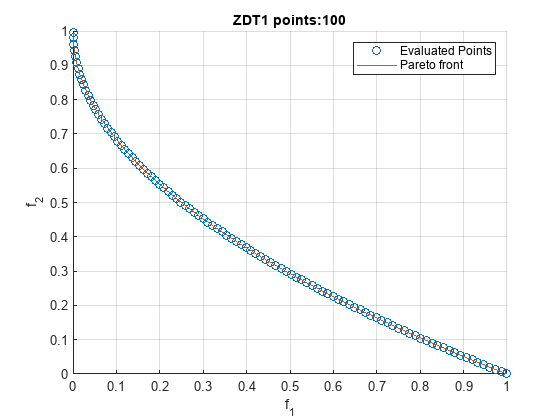

figure;
hold on;
scatter(f1_vals, f2_vals);
plot(f1_vals, f2_vals);
hold off;
xlim([0 1]);
xlabel("f_1")
ylim([0 1]);
ylabel("f_2");
grid on;
title(strcat("ZDT1 points:", num2str(RefPoints)))
legend('Evaluated Points', 'Pareto front')

## Functions

function ret = f1(x)
    ret = x(1);
end

function ret = f2(x)
    G = 1 + sum(x(2:end));
    ret = G * (1 - sqrt(x(1) ./ G));
end

function ret = ASFCondition(x, Fn, z, w)
    ret = (Fn(x) - z) ./ w - x(end);
end

function [c, ceq] = Constraint(x, C1, C2)
    c = [C1(x); C2(x)];
    ceq = [];
end

% Handles alpha
function ret = ASF(x, Functions, M, z, w)
    C = zeros([1 M]);

    x = x(1:end-1);  % alpha is not required
    for i = 1:M
        C(i) = (Functions{i}(x) - z(i)) ./ w(i);
    end
    ret = max(C);
end